# **Script to clean and analyze data for task switching  paradigm**

We are looking at the influence of BlockType (different combinations of the conditions), trial type (switch vs stay), and switch dimensions (sequential predictability, switch distance, and discriminability) on RT and accuracy.

Danielle Kurtin, July 2022

**Table of contents:**

- Setup and organizing data

- Overall performance (Correct vs Incorrect)

- Reaction time cleaning/organizing, some plots to see the data

- Transforming the data for RT LMEM

- The effect of trial type (switch or stay) and block on RT

- Post hocs

- The effect of trial type and switch dims on RT

- Accuracy cleaning/organizing, some plots to see the data

- The effect of trial type (switch or stay) and block on accuracy

- The effect of trial type and switch dims on accuracy

- Post hocs

**Model checklist: **

Make sure data is suitable for model- RT data are rank inverse transfored to a normal distribution; Acc data uses binomial distribution. Subject is included as a random effect.

**1. Setup and organzing data**

% Adding packages we need
% For Plotting
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\gramm-master'); 
% For winsorize
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\winsorize');
% For emmeans
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\emmeans');
% For permutation test
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\permutation_test')
% For the data
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\G_TaskSwitching\BehavioralAnalysis')

% For the old drafts
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\G_TaskSwitching\BehavioralAnalysis\OldDrafts\')

% For violin plots
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\violinplot')
% For effect size
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\CalcCohens')
% For colors
addpath('C:\Users\dk00549\OneDrive - University of Surrey\Documents\Surrey\MATLAB\PluginsProgramsToolboxes\linspecer')

% Read in the data
df = readtable('Study2.csv') ;

% Determine how many trials each participant has
Ntrials = groupcounts(df,{'subject'}) ;

% Sorting the rows in df by participant ID, so groupcounts and df are in
% the same order
df = sortrows(df,'subject','ascend') ;
Ntrials = groupcounts(df,{'subject'});
trial_vect = cumsum([Ntrials.GroupCount]);
index = 1;

**2. Overall performance- Correct vs Incorrect**

% Creating a column for Correct answers 
Correct = (df.response==df.targetflanker);
Correct=double(Correct);
df.Correct = Correct;

% Looking for missing answers per participant
answers = groupcounts(df,{'Correct','subject'});
answer = answers.Correct;

Random1=zeros(height(df)/2,1);
Random2=ones(height(df)/2,1);
Random=[Random1;Random2];
df.Random=Random;

**3. Reaction Time data cleaning, plots, and descriptive stats**

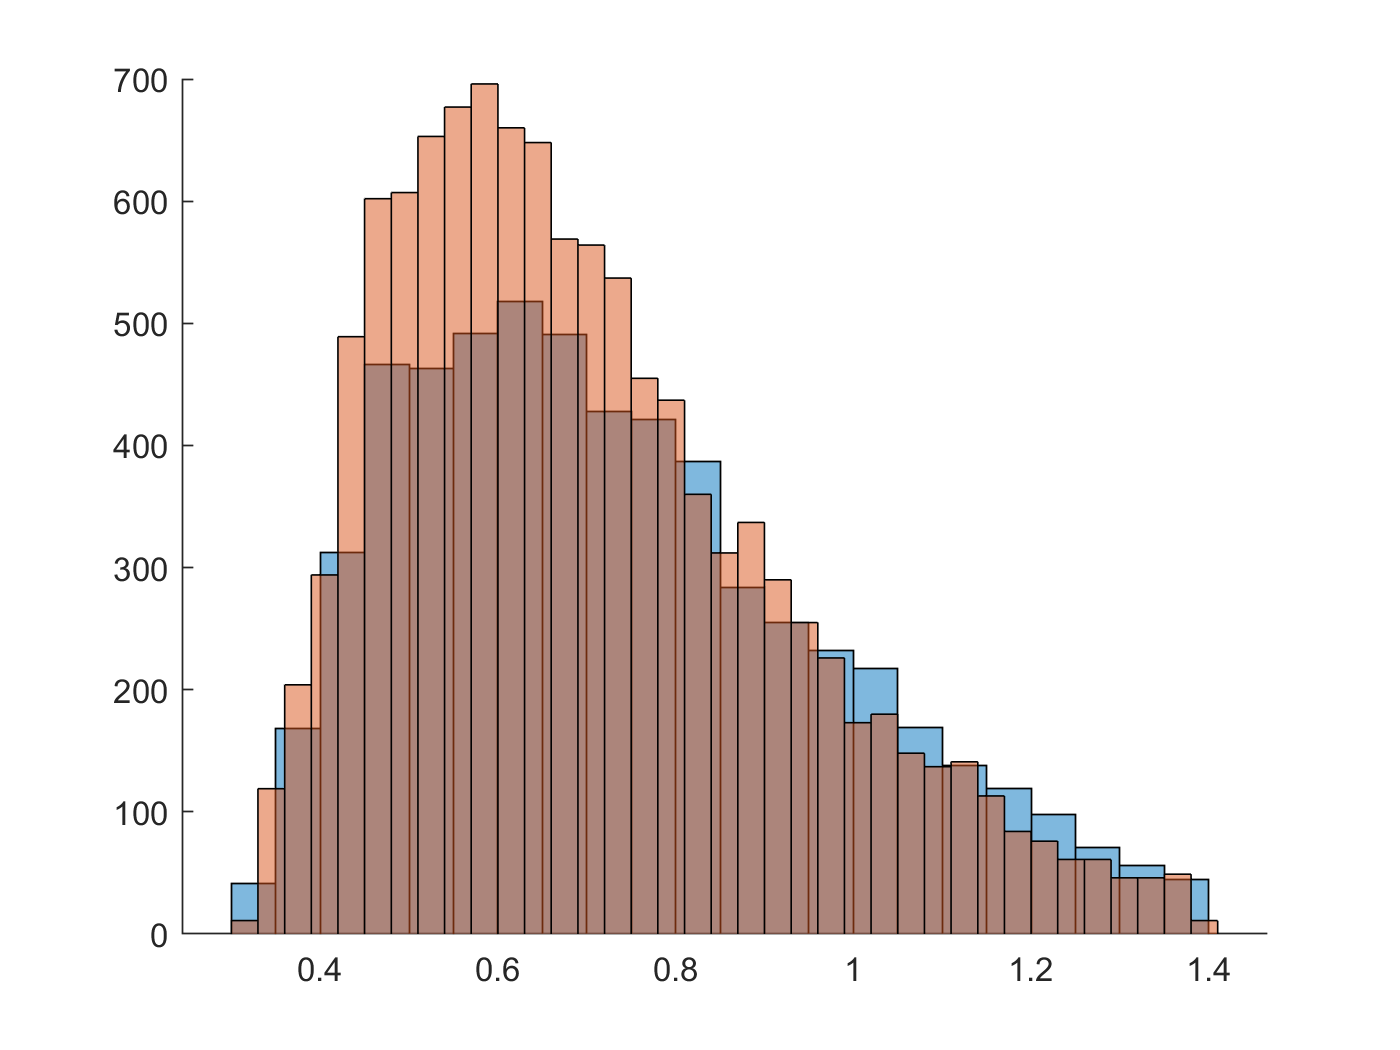

% Trimming off 2% of the data
df_rt = df ; 
p = prctile(df_rt.RT, [1 99]);
todelete1 = df_rt.RT <= p(1) ;
df_rt(todelete1,:) = [] ;
todelete2 = df_rt.RT >= p(2) ;
df_rt(todelete2,:) = [] ;

%Winsorise le data
% winsorising(df_clean_ext.RT);

% First create a variable for RT correct and another for RT incorrect
RT_Correct = [];
RT_Incorrect = [];
for ii=1:length(df_rt.Correct)
    if (df_rt.Correct(ii)==1)
        RT_Correct(ii) = df_rt.RT(ii);
        RT_Incorrect(ii) = NaN;
    else
        RT_Correct(ii) = NaN;
        RT_Incorrect(ii) = df_rt.RT(ii);
    end
end

df_rt.RT_Correct = RT_Correct';
df_rt.RT_Incorrect = RT_Incorrect';
%Because non-responded RTs are nan, RT_Incorrect will have nans

figure()
hold on
histogram(RT_Correct','FaceAlpha',0.5)
histogram(RT_Incorrect','FaceAlpha',0.5)

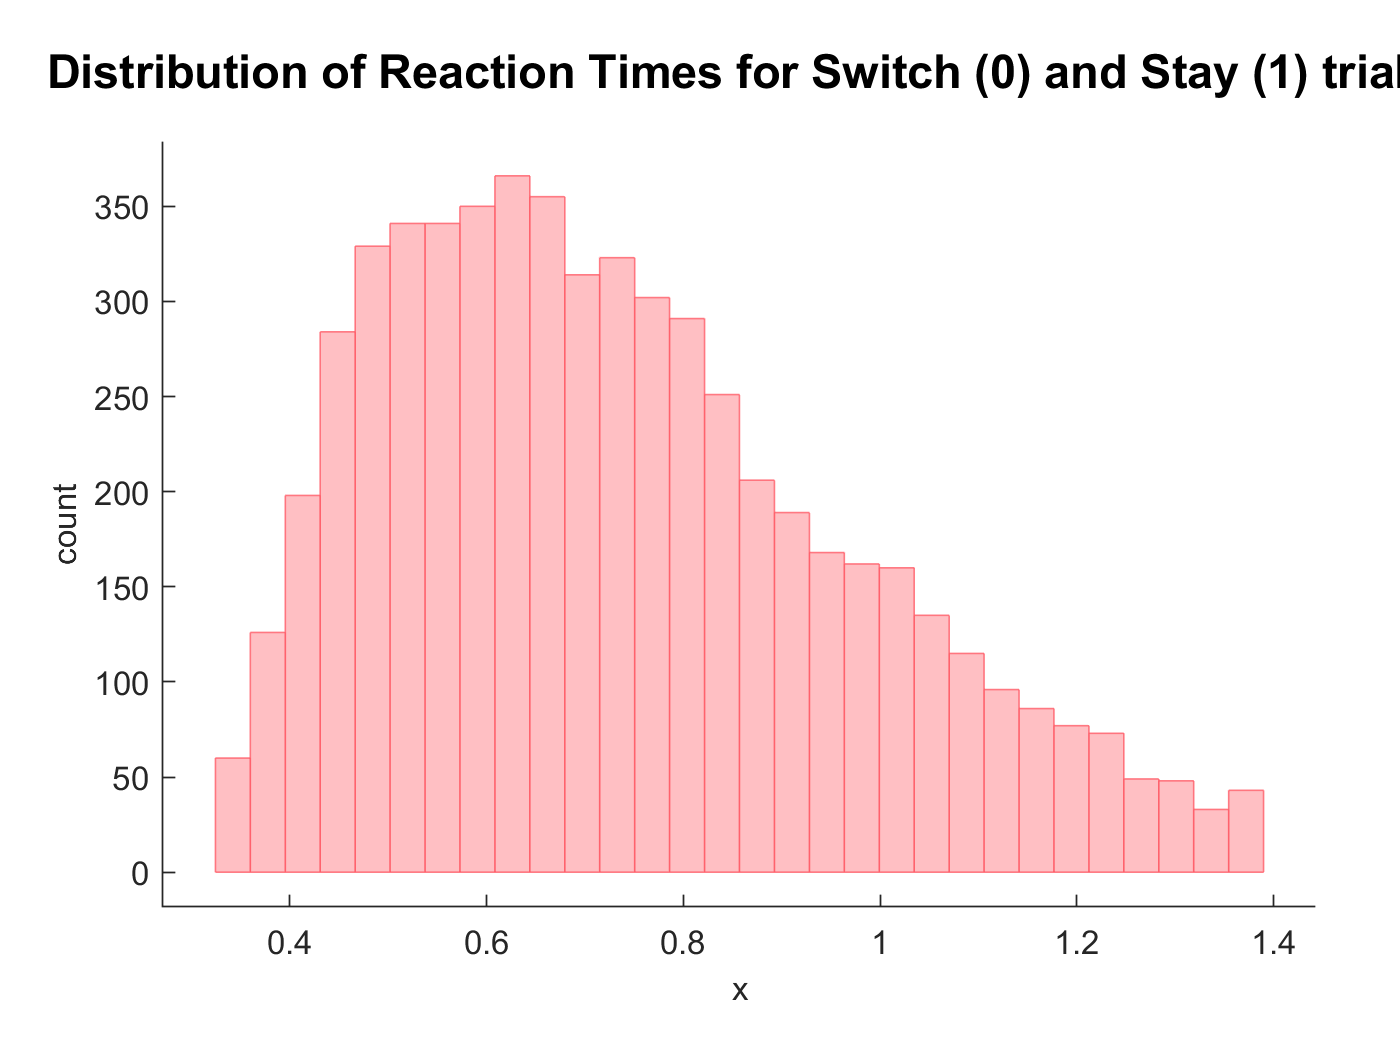


RT_Correct=RT_Correct';

% remove nans
toDelete=isnan(df_rt.RT_Correct);
df_rt(toDelete,:)=[];

% Check distribution
dt=gramm('x',df_rt.RT,'color', df_rt.Correct);
dt.stat_bin('geom','overlaid_bar');
dt.set_title('Distribution of Reaction Times for Switch (0) and Stay (1) trials');
figure
dt.draw();


% Summary of overall MRT Stats
columns = df_rt(:,{'RT_Correct','RT_Incorrect'});
RTStats = grpstats(columns,[],{'mean','median','sem','std'})

RTStats = 1×9 table
           GroupCount    mean_RT_Correct    median_RT_Correct    sem_RT_Correct    std_RT_Correct    mean_RT_Incorrect    median_RT_Incorrect    sem_RT_Incorrect    std_RT_Incorrect
           __________    _______________    _________________    ______________    ______________    _________________    ___________________    ________________    ________________

    All       5871           0.73634             0.69808           0.0030689          0.23515               NaN                   NaN                  NaN                 NaN       




% Summary of Acc per person for LEiDA
statarray_df = grpstats(df,{'subject','Run'},'nansum','DataVars',{'accuracy'});
statarray_df.mean_accuracy = statarray_df.nansum_accuracy./statarray_df.GroupCount;

% Make sure data is categorical
df_rt.temporal=categorical(df_rt.temporal);
df_rt.perceptual=categorical(df_rt.perceptual);
df_rt.spatial=categorical(df_rt.spatial);
df_rt.BlockType=categorical(df_rt.BlockType);
df_rt.TType=categorical(df_rt.TType);

% Make sure data is categorical
df.temporal=categorical(df.temporal);
df.perceptual=categorical(df.perceptual);
df.spatial=categorical(df.spatial);
df.BlockType=categorical(df.BlockType);
df.TType=categorical(df.TType);

**4. Transforming data for LMEM**

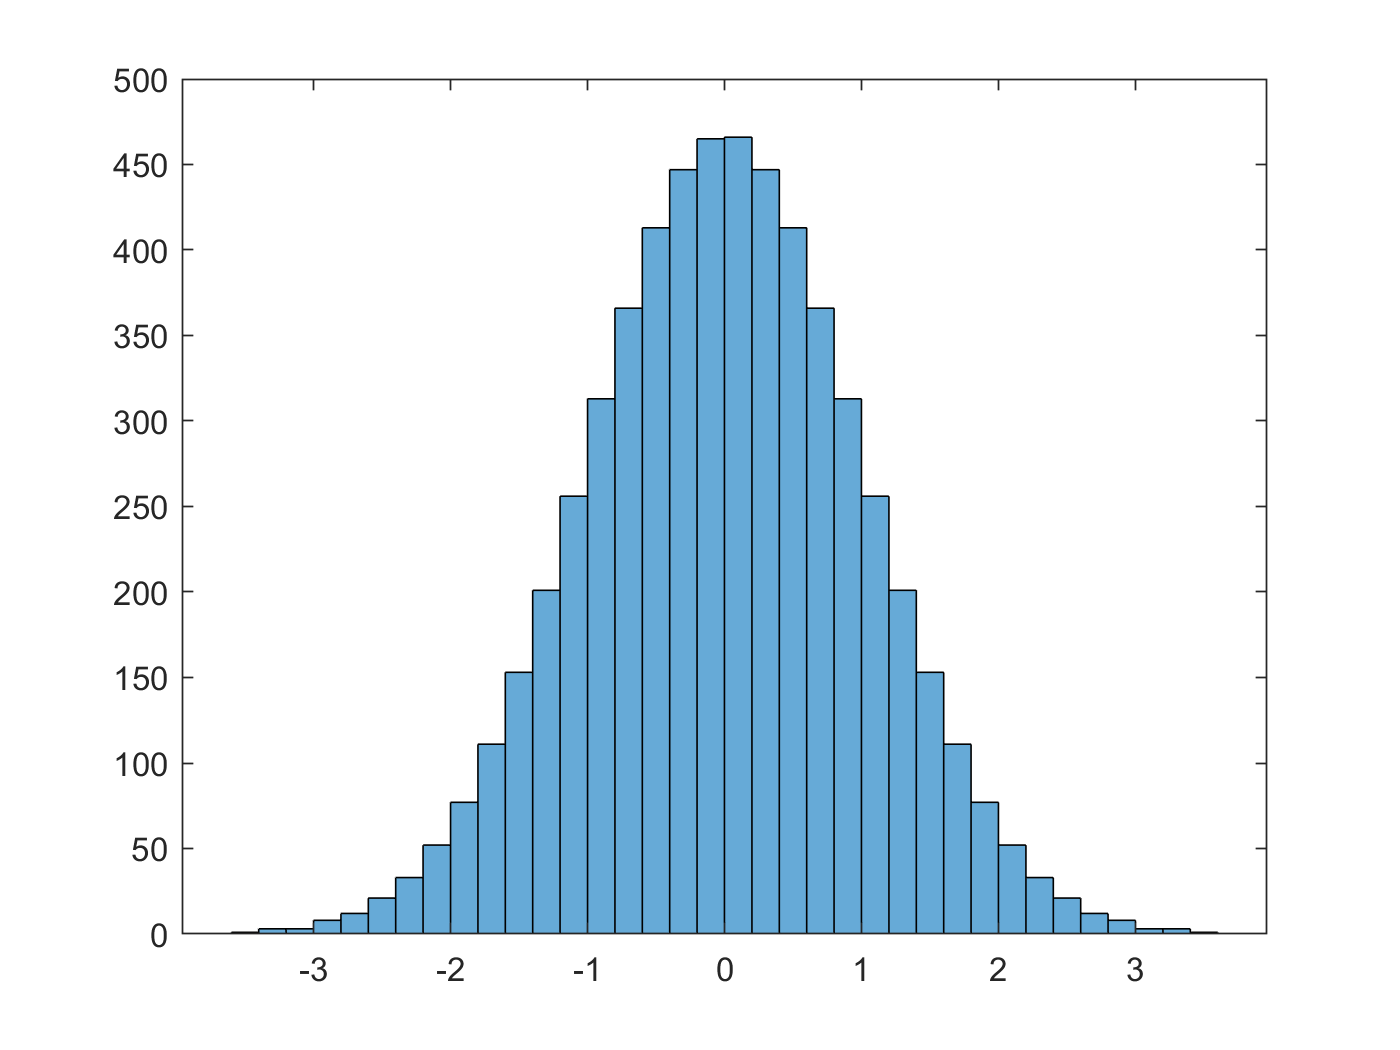

df_rt.RT_CorrectTrans = InvRankTrans(df_rt.RT_Correct);

figure()
histogram(df_rt.RT_CorrectTrans)

**5 The effect of trial type (switch or stay) and block on RT**

lme2 = fitglme(df_rt,'RT_CorrectTrans ~ TType*BlockType + (1|subject)', 'Distribution', 'Normal'); 
disp(lme2)

Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations            5871
    Fixed effects coefficients          16
    Random effects coefficients         25
    Covariance parameters                2
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    RT_CorrectTrans ~ 1 + BlockType*TType + (1 | subject)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    15314    15435    -7639.2          15278   

Fixed effects coefficients (95% CIs):
    Name                           Estimate      SE          tStat        DF      pValue        Lower    
    {'(Intercept)'        }          -0.16574     0.08165      -2.0298    5855      0.042417      -0.3258
    {'BlockType_2'        }         -0.012784    0.051387     -0.24878    5855       0.80354     -0.11352

anova(lme2)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat      DF1    DF2     pValue    
    {'(Intercept)'    }         4.1203    1      5855      0.042417
    {'BlockType'      }        0.84961    7      5855       0.54598
    {'TType'          }          94.64    1      5855    3.3611e-22
    {'BlockType:TType'}        0.40796    7      5855       0.89798


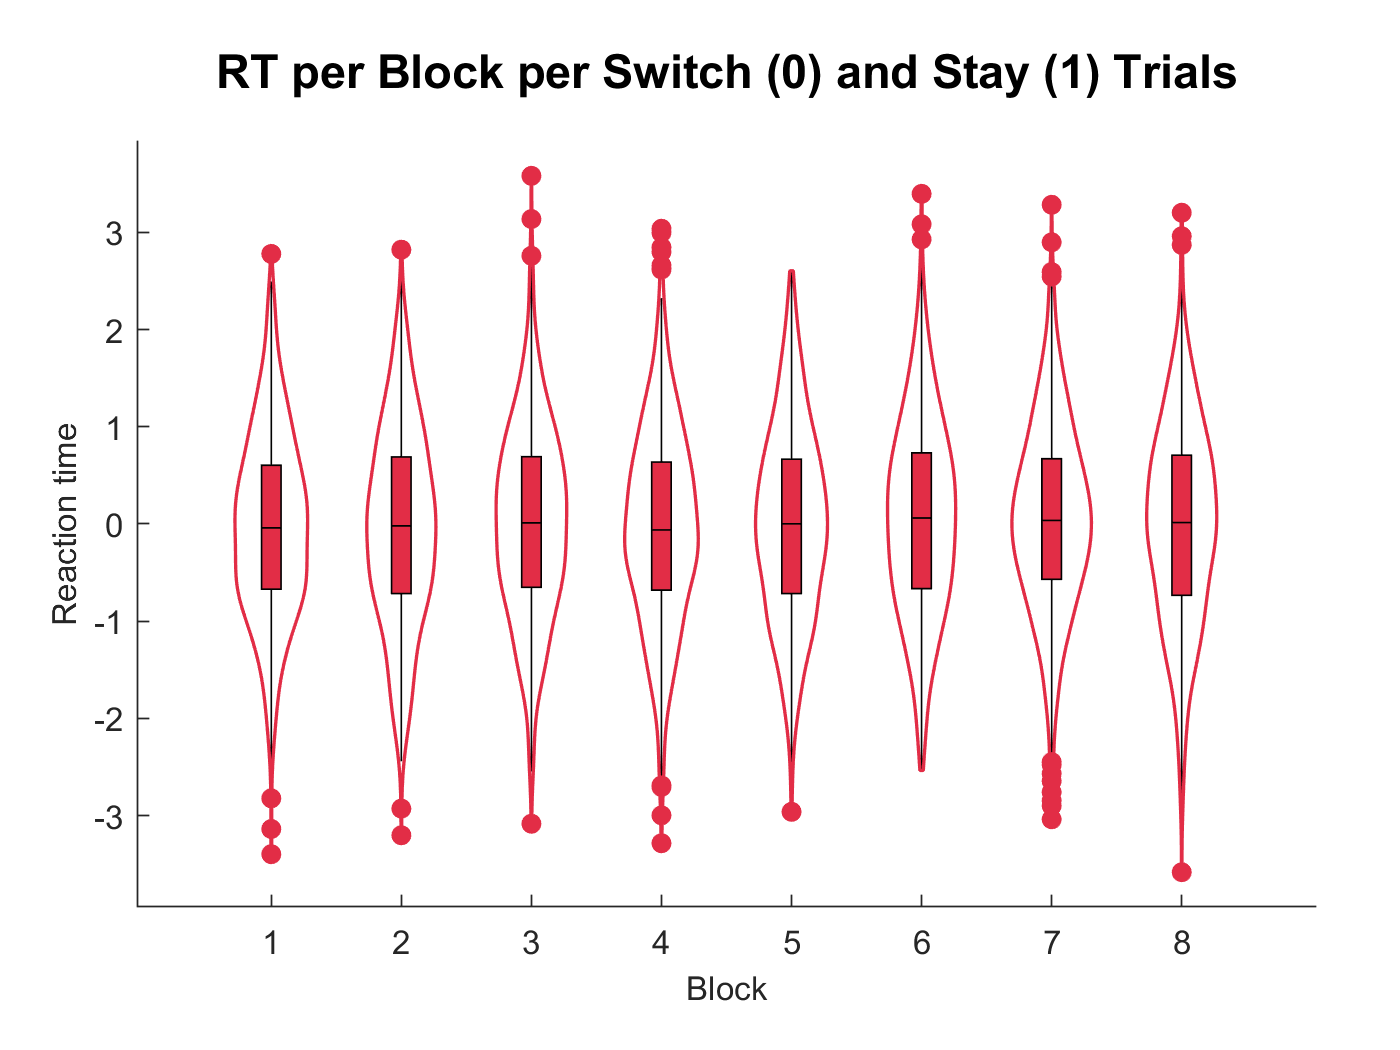

% There is a significant main effect of trial type (F(1,5855)=151,
% p=3.4e-22) on RT. There is not a significant main effect of block
% (F(7,5855)=0.85, p=0.55) or an interactive effect of block and trial type
% (F(7,5867)=0.41, p=0.90) on RT.

% RT per Block per trial type
C=linspecer(2);
dt=gramm('x',df_rt.BlockType,'y',df_rt.RT_CorrectTrans);
dt.stat_boxplot('width',0.15);
dt.stat_violin('normalization','area','dodge',0.7,'fill','edge');
dt.set_title('RT per Block per Switch (0) and Stay (1) Trials');
dt.set_color_options('map',C(2,:));
dt.set_color_options('lightness',50);
% dt.axe_property('YLim',[0 1.4]);
dt.set_names('x','Block','y','Reaction time');
figure
dt.draw();

**6 Post hocs for the effect of trial type on RT**

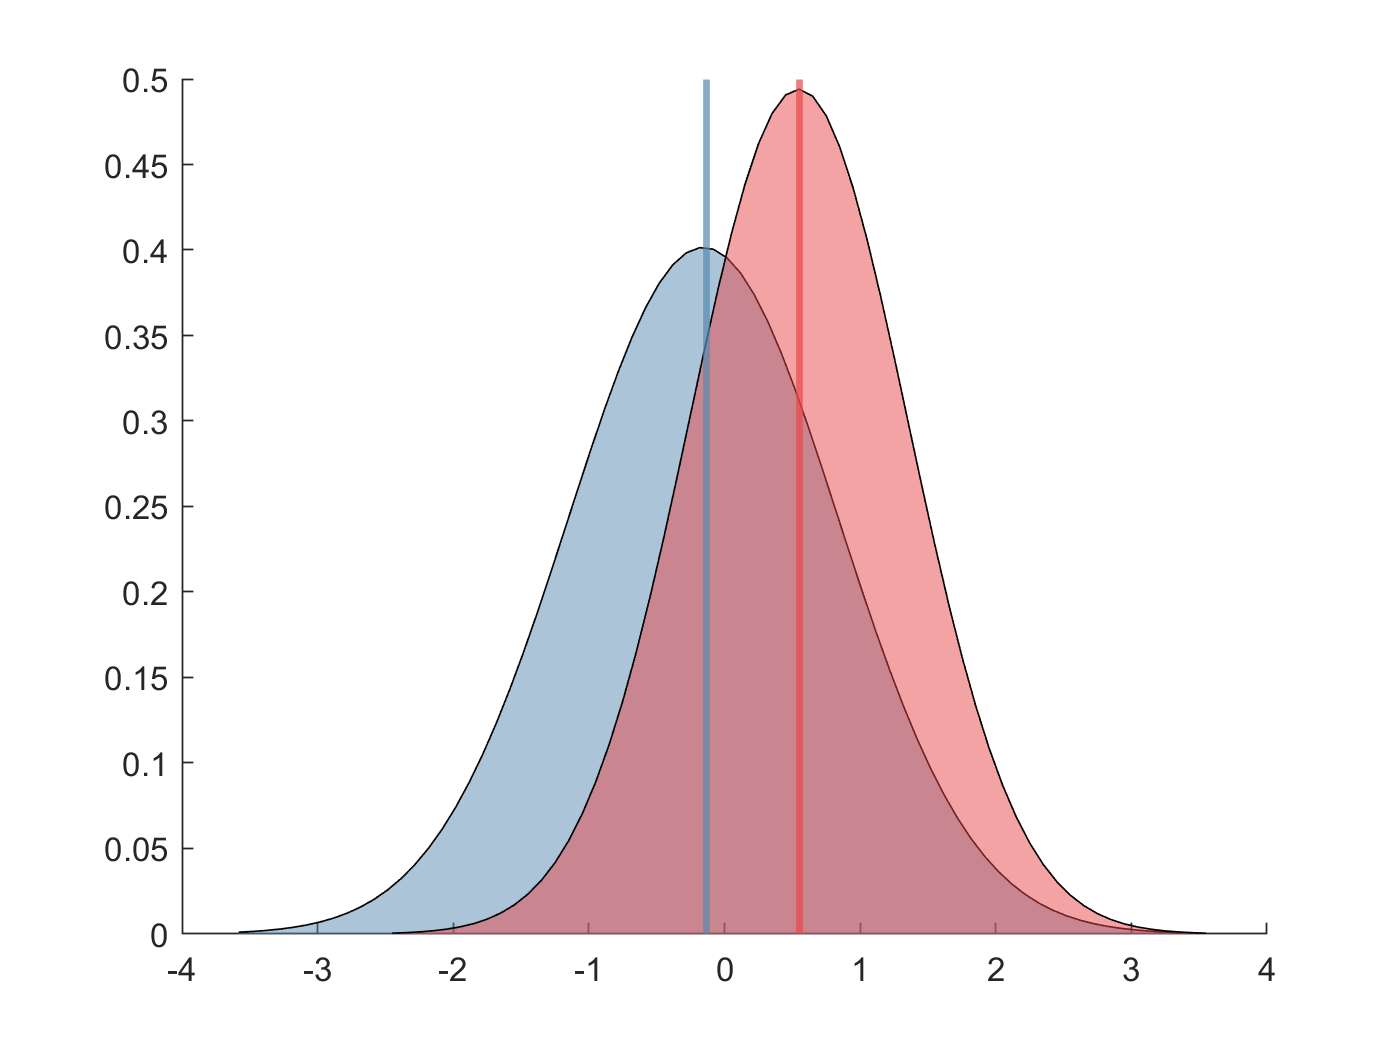

C=linspecer(2);

% % Do TTests for diff levels of discrim
Switch=df_rt.TType==categorical(1);
Stay=df_rt.TType==categorical(0);

Switch=df_rt.RT_CorrectTrans(Switch);
Stay=df_rt.RT_CorrectTrans(Stay);

Swpd = fitdist(Switch,'Normal');
Stpd = fitdist(Stay,'Normal');

Swx_values=min(Switch):0.1:max(Switch);
Swy = pdf(Swpd,Swx_values);
Stx_values=min(Stay):0.1:max(Stay);
Sty = pdf(Stpd,Stx_values);

Swm=median(Swy);
Stm=median(Sty);

figure()
hold on
a=area(Stx_values,Sty);
a.FaceColor = C(1,:);
a.FaceAlpha = 0.5;
b=area(Swx_values,Swy);
b.FaceColor = C(2,:);
b.FaceAlpha = 0.5;
xline(mean(a.XData),'Color',C(1,:),"LineWidth",2)
xline(mean(b.XData),'Color',C(2,:),"LineWidth",2)



% [h,p,chi,stats] = ttest2(Switch,Stay)
% d=computeCohen_d(Switch,Stay)
% % Switch trials show a significantly longer RT than stay trials
% % (t(5869)=23, p=9.0e-116, D=0.73).

**7. The effect of switch dimensions and trial type on RT**

lme = fitglme(df_rt,'RT_CorrectTrans ~ TType*temporal + (1|subject) ', 'Distribution', 'Normal');
anova(lme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                      FStat      DF1    DF2     pValue    
    {'(Intercept)'   }         4.4529    1      5867      0.034885
    {'temporal'      }         1.3238    1      5867       0.24995
    {'TType'         }         352.62    1      5867    1.9129e-76
    {'temporal:TType'}        0.52151    1      5867       0.47023


% There is not a significant main effect of sequential predictability
% (F(1,5867)=1.3, p=0.25) on RT. There is not an interactive effect of
% sequential predictability (F(1,5867)=0.52, p=0.47) on RT.

lme = fitglme(df_rt,'RT_CorrectTrans ~ TType*perceptual + (1|subject)', 'Distribution','Normal');
anova(lme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                        FStat      DF1    DF2     pValue   
    {'(Intercept)'     }         3.9234    1      5867     0.047664
    {'perceptual'      }        0.15613    1      5867      0.69276
    {'TType'           }         327.13    1      5867    3.382e-71
    {'perceptual:TType'}        0.17644    1      5867      0.67447


% There is not a significant main effect of perceptual predictability (F(1,5867)=0.15,
% p=0.69) on RT. There is not a significant interactive effect of
% perceptual predictability and trial type (F(1,5867)=0.18, p=0.67) on RT.

lme = fitglme(df_rt,'RT_CorrectTrans ~ TType*spatial + (1|subject)', 'Distribution', 'Normal');
anova(lme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                     FStat      DF1    DF2     pValue    
    {'(Intercept)'  }         3.2898    1      5867      0.069764
    {'spatial'      }        0.31658    1      5867       0.57369
    {'TType'        }         355.56    1      5867    4.7762e-77
    {'spatial:TType'}        0.35488    1      5867       0.55138


% There is not a significant main effect of spatial predictability
% (F(1,5867)=0.32, p=0.57) on RT or a significant, interactive effect of
% spatial predictability and trial type (F(1,5867)=0.35, p=0.55) on RT. 


**8. Accuracy plots and descriptive stats **

statarray_df_clean_ext = grpstats(df,{'subject','BlockType','TType'},'nansum','DataVars',{'accuracy'});
statarray_df_clean_ext.mean_accuracy = statarray_df_clean_ext.nansum_accuracy./statarray_df_clean_ext.GroupCount;

% Summary of overall mean Accuracy Stats
columns = statarray_df_clean_ext(:,{'mean_accuracy'});
AccStats = grpstats(columns,[],{'mean','std','median','sem'})

AccStats = 1×5 table
           GroupCount    mean_mean_accuracy    std_mean_accuracy    median_mean_accuracy    sem_mean_accuracy
           __________    __________________    _________________    ____________________    _________________

    All       400             0.63975              0.096168               0.65217               0.0048084    


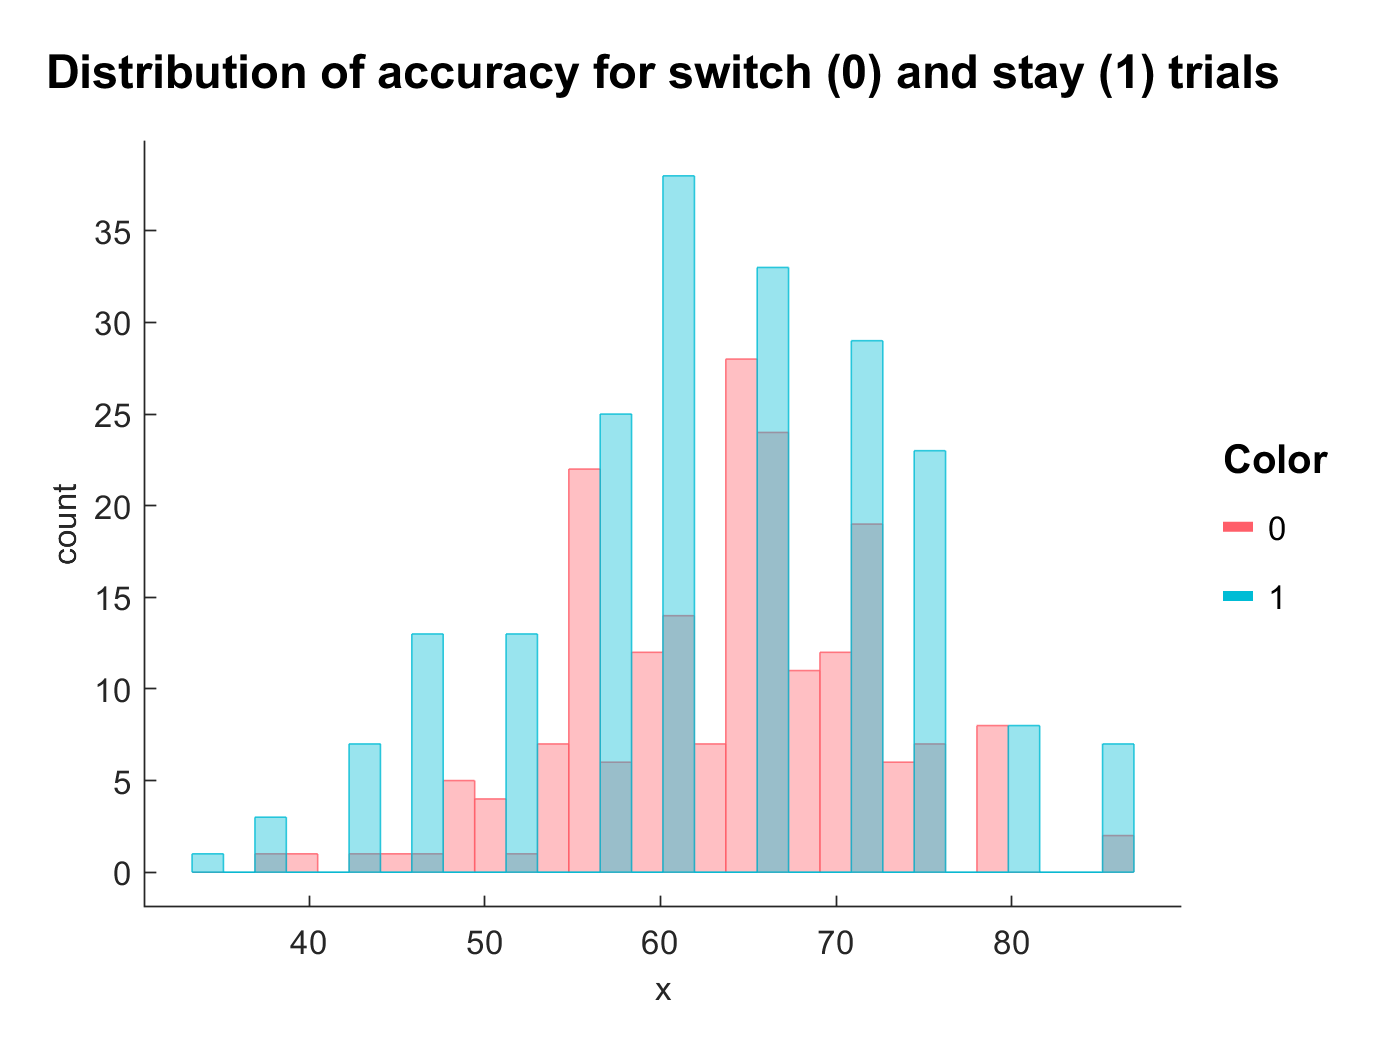

% This is not a binomial or inverse Gaussian distribution

statarray_df = grpstats(df,{'subject','Run'},'nansum','DataVars',{'accuracy'});
statarray_df.mean_accuracy = statarray_df.nansum_accuracy./statarray_df.GroupCount;

dt=gramm('x',(statarray_df_clean_ext.mean_accuracy)*100,'color', statarray_df_clean_ext.TType);
dt.stat_bin('geom','overlaid_bar');
dt.set_title('Distribution of accuracy for switch (0) and stay (1) trials');
figure
dt.draw();


dt=gramm('x',statarray_df_clean_ext.BlockType,'y',(statarray_df_clean_ext.mean_accuracy)*100);
dt.stat_violin('normalization','area','dodge',0.7,'fill','edge');
dt.stat_boxplot('width',0.15);
dt.set_color_options('map',C(2,:))

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


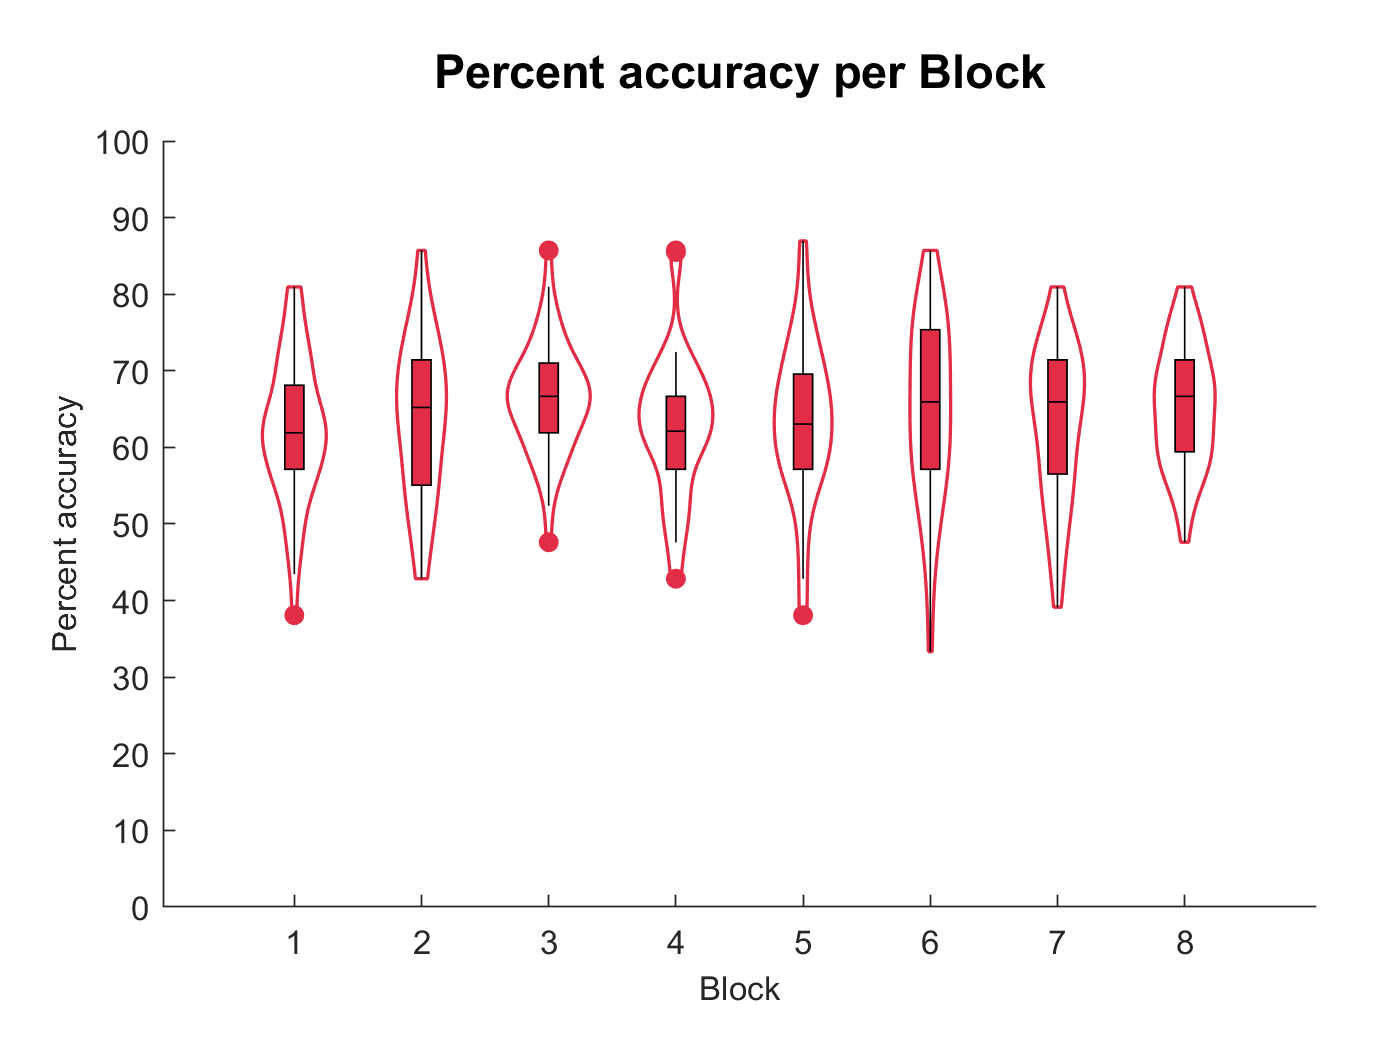

dt.set_color_options('lightness',50);
dt.axe_property('YLim',[0 100]);
dt.set_title('Percent accuracy per Block');
dt.set_names('x','Block','y','Percent accuracy');
figure
dt.draw();

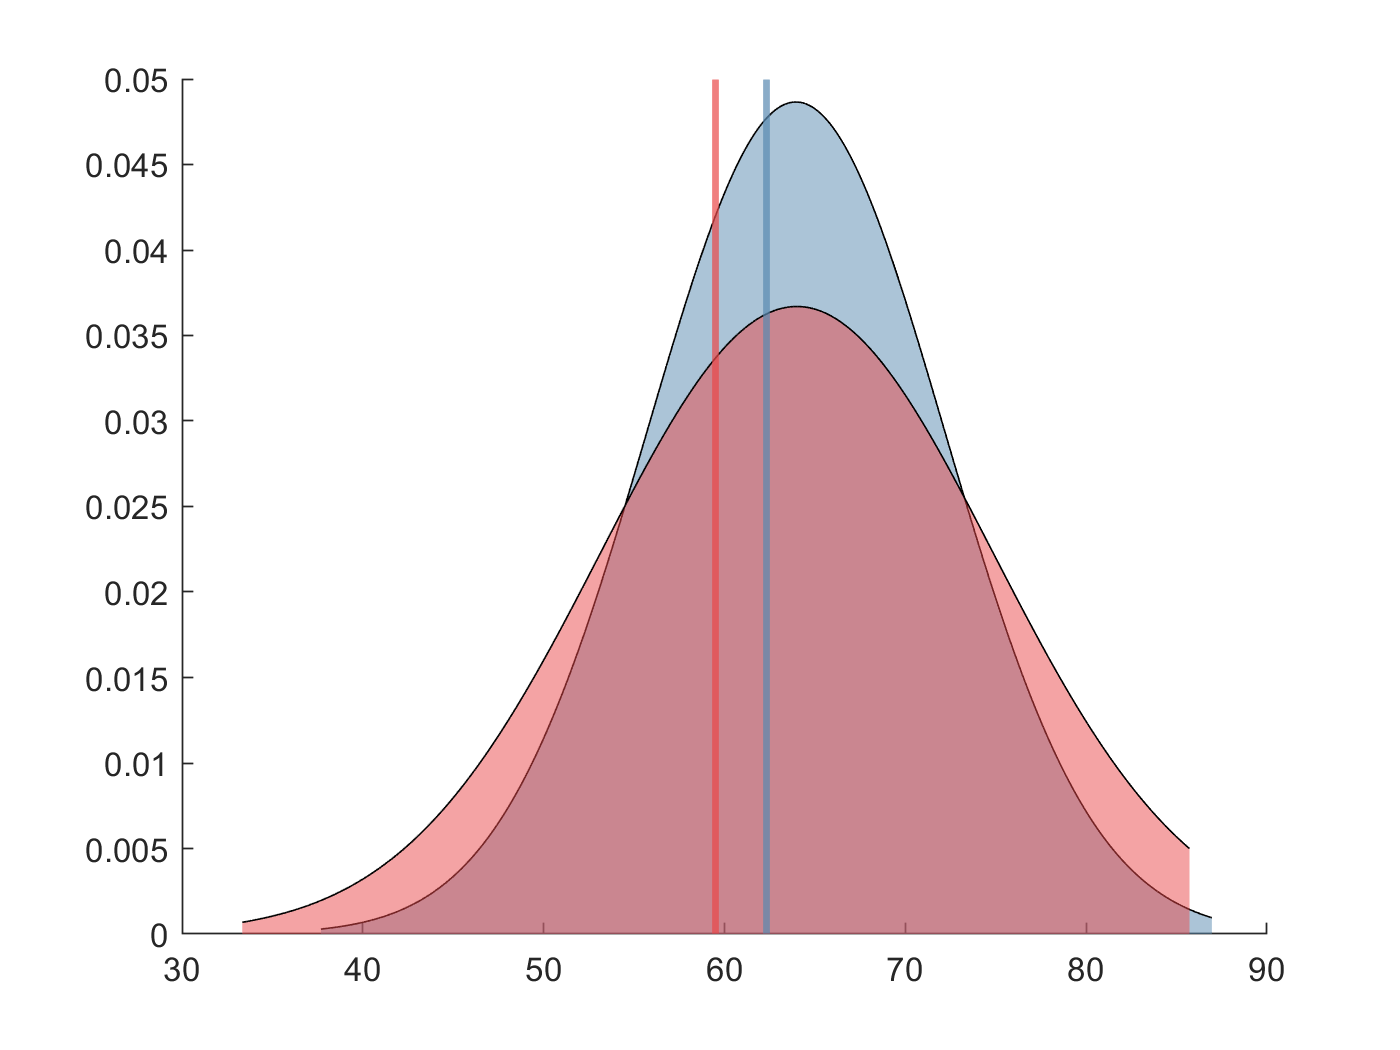

 
Switch=statarray_df_clean_ext.TType==categorical(1);
Stay=statarray_df_clean_ext.TType==categorical(0);

Switch=(statarray_df_clean_ext.mean_accuracy(Switch)*100);
Stay=(statarray_df_clean_ext.mean_accuracy(Stay)*100);

C=linspecer(2);

% Get the mu, sigma, and intervals for normal distributions of switch and
% stay data
Swpd = fitdist(Switch,'Normal');
Stpd = fitdist(Stay,'Normal');

% Create the pdf - the value of the data on the X, and the Y is
% the frequency of occurrence. . .  
Swx_values=min(Switch):0.01:max(Switch);
Swy = pdf(Swpd,Swx_values);
Stx_values=min(Stay):0.01:max(Stay);
Sty = pdf(Stpd,Stx_values);

% Add lines 
Swm=mean(Swy);
Stm=mean(Sty);

figure()
hold on
a=area(Stx_values,Sty);
a.FaceColor = C(1,:);
a.FaceAlpha = 0.5;
xline(median(a.XData),'Color',C(1,:),"LineWidth",2)
b=area(Swx_values,Swy);
b.FaceColor = C(2,:);
b.FaceAlpha = 0.5;
xline(mean(b.XData),'Color',C(2,:),"LineWidth",2)


% Assessing whether performance is above chance
[h,p,chi,stats]=ttest2(df.Correct,df.Random)

h = 1

p = 5.6972e-223

chi =    -0.1746
   -0.1545


stats = struct with fields:
    tstat: -32.1027
       df: 35998
       sd: 0.4863



d = computeCohen_d(df.Correct,df.Random)

d = -0.3384

% Accuracy performance was significantly higher (t(35998)=32, p=5.7e-223, D=0.34) than chance 

**9. The effect of trial type (switch or stay) and block on Acc**

lme = fitglme(df,'Correct ~ TType*BlockType + (1|subject)','Distribution',"Binomial",'Link',"logit");
anova(lme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                       FStat      DF1    DF2      pValue    
    {'(Intercept)'    }         88.062    1      17984    7.0817e-21
    {'BlockType'      }         1.8486    7      17984      0.073645
    {'TType'          }        0.89229    1      17984       0.34487
    {'BlockType:TType'}        0.77786    7      17984       0.60583


% There is not a significant main effect of block (F(7,17984)=1.8, p=0.07) 
% on accuracy. There is not a significant, main effect of trial type
% (F(1,17984)=0.89, p=0.34) or a significant, interactive effect of block and trial type (F(1,17984)=0.78, p=0.61) on
% accuracy. 

Switch=df.TType==categorical(0);
Stay=df.TType==categorical(1);

Switch=df.Correct(Switch);
Stay=df.Correct(Stay);

[h,p,chi,stats]=ttest2(Switch,Stay)

h = 1

p = 0.0058

chi =     0.0066
    0.0392


stats = struct with fields:
    tstat: 2.7575
       df: 17998
       sd: 0.4721



d = computeCohen_d(Switch,Stay)

d = 0.0486


% creating .mat of acc per subj per block - need to figure out wht subj
% to delete (sme as the one for ROI Comp script). Could be subj 17- will go
% ahead with that
acc= grpstats(df,{'subject','block'},'nansum','DataVars',{'accuracy'});
acc.mean_accuracy = acc.nansum_accuracy./acc.GroupCount;
acc(113:120,:)=[];

C=linspecer(2)

C =     0.3467    0.5360    0.6907
    0.9153    0.2816    0.2878


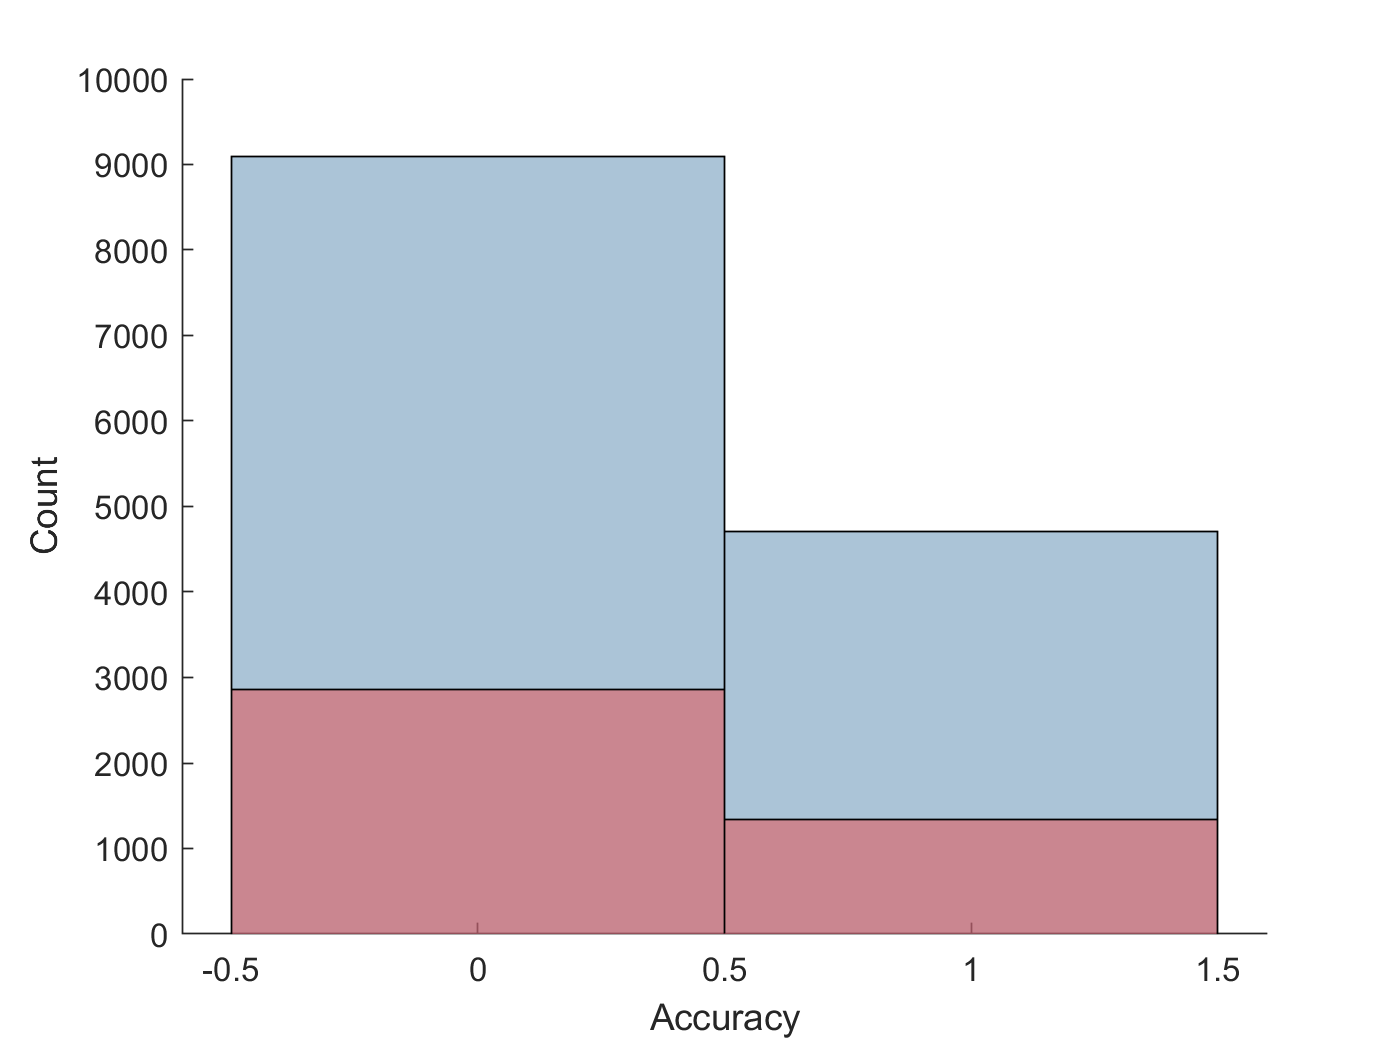

figure()
hold on
histogram(Switch,'FaceColor',C(1,:),'FaceAlpha',0.5)
histogram(Stay,'FaceColor',C(2,:),'FaceAlpha',0.5)
xlabel('Accuracy');
ylabel('Count');

**10. The effect of trial type (switch or stay) and switch dims on Acc**

lme = fitglme(df,'Correct ~ TType*temporal + (1|subject)','Distribution',"Binomial",'Link',"logit");
anova(lme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                      FStat     DF1    DF2      pValue    
    {'(Intercept)'   }        226.35    1      17996    7.6128e-51
    {'temporal'      }        4.5884    1      17996      0.032202
    {'TType'         }        8.3964    1      17996     0.0037642
    {'temporal:TType'}        1.8012    1      17996       0.17958


% There is a significant main effect of sequential predictability (F(1,17996)=4.6,
% p=0.03) on accuracy, and there is not an interactive effect of sequential predictability
% and trial type (F(1,17996)=1.8, p=0.18) on accuracy.

lme = fitglme(df,'Correct ~ TType*perceptual + (1|subject)','Distribution',"Binomial",'Link',"logit");
anova(lme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                        FStat       DF1    DF2      pValue    
    {'(Intercept)'     }          244.71    1      17996    8.4774e-55
    {'perceptual'      }          0.4929    1      17996       0.48264
    {'TType'           }          3.1126    1      17996      0.077704
    {'perceptual:TType'}        0.077634    1      17996       0.78053


% There is not a significant main effect of perceptual predictability (F(1,17996)=0.49, p=0.48)
% on accuracy. There is not a significant interactive effect of perceptual
% predictability (F(1,17996)=0.08, p=0.78) on accuracy. 

lme = fitglme(df,'Correct ~ TType*spatial + (1|subject)','Distribution',"Binomial",'Link',"logit");
anova(lme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                     FStat      DF1    DF2      pValue    
    {'(Intercept)'  }         263.28    1      17996    8.6528e-59
    {'spatial'      }         0.4929    1      17996       0.48264
    {'TType'        }        0.85065    1      17996       0.35638
    {'spatial:TType'}         2.1703    1      17996       0.14072



% There is not a significant main effect of spatial predictability (F(1,17996)=0.49,
% p=0.48) on accuracy. There is not a significant interactive effect of spatial predictability 
% (F(1,17996)=2.2, p=0.14) on accuracy. 

**11. Post hocs for the effect of seq pred on accuracy**

% The effect of sequential predictability on accuracy
Easy=df.temporal==categorical(1);
Hard=df.temporal==categorical(2);

Easy=df.Correct(Easy);
Hard=df.Correct(Hard);

[p,h,stats]=signrank(Easy,Hard)

p = 0.0859

h = logical
   0


stats = struct with fields:
          zval: 1.7175
    signedrank: 4.0163e+06


% d = computeCohen_d(Easy,Hard)

**11. Also running post hocs using Wald contrast tests with emmeans**

lme = fitglme(df,'Correct ~ TType*temporal + (1|subject)','Distribution',"Binomial",'Link',"logit");
anova(lme)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                      FStat     DF1    DF2      pValue    
    {'(Intercept)'   }        226.35    1      17996    7.6128e-51
    {'temporal'      }        4.5884    1      17996      0.032202
    {'TType'         }        8.3964    1      17996     0.0037642
    {'temporal:TType'}        1.8012    1      17996       0.17958


emm=emmeans(lme);
% L is a nx1 logical vector of contrast coefficients, where emm.table has 
% n rows. 
L=double(emm.table.temporal)';
Wald=contrasts_wald(lme,emm,L);

Wald.pVal

ans = 4.4007e-70

Wald.Wald

ans = 17.7748

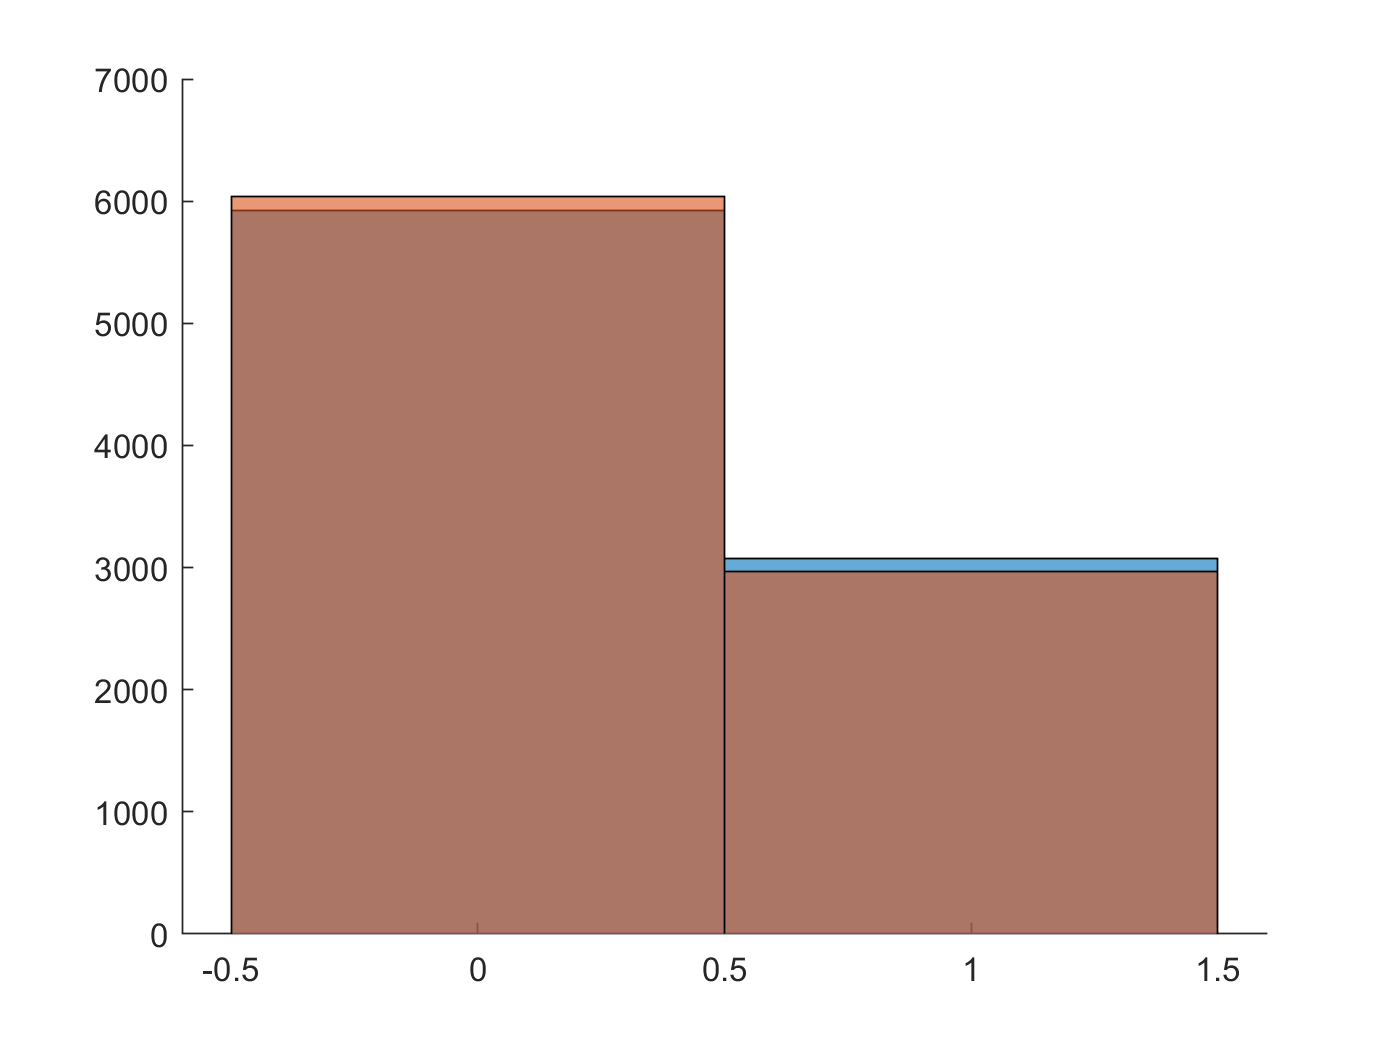

% So there's a sig main effect w/ emmeans indicating higher pred = higher
% acc

% Easy vs Hard seq pred
figure()
hold on
histogram(Easy)
histogram(Hard)

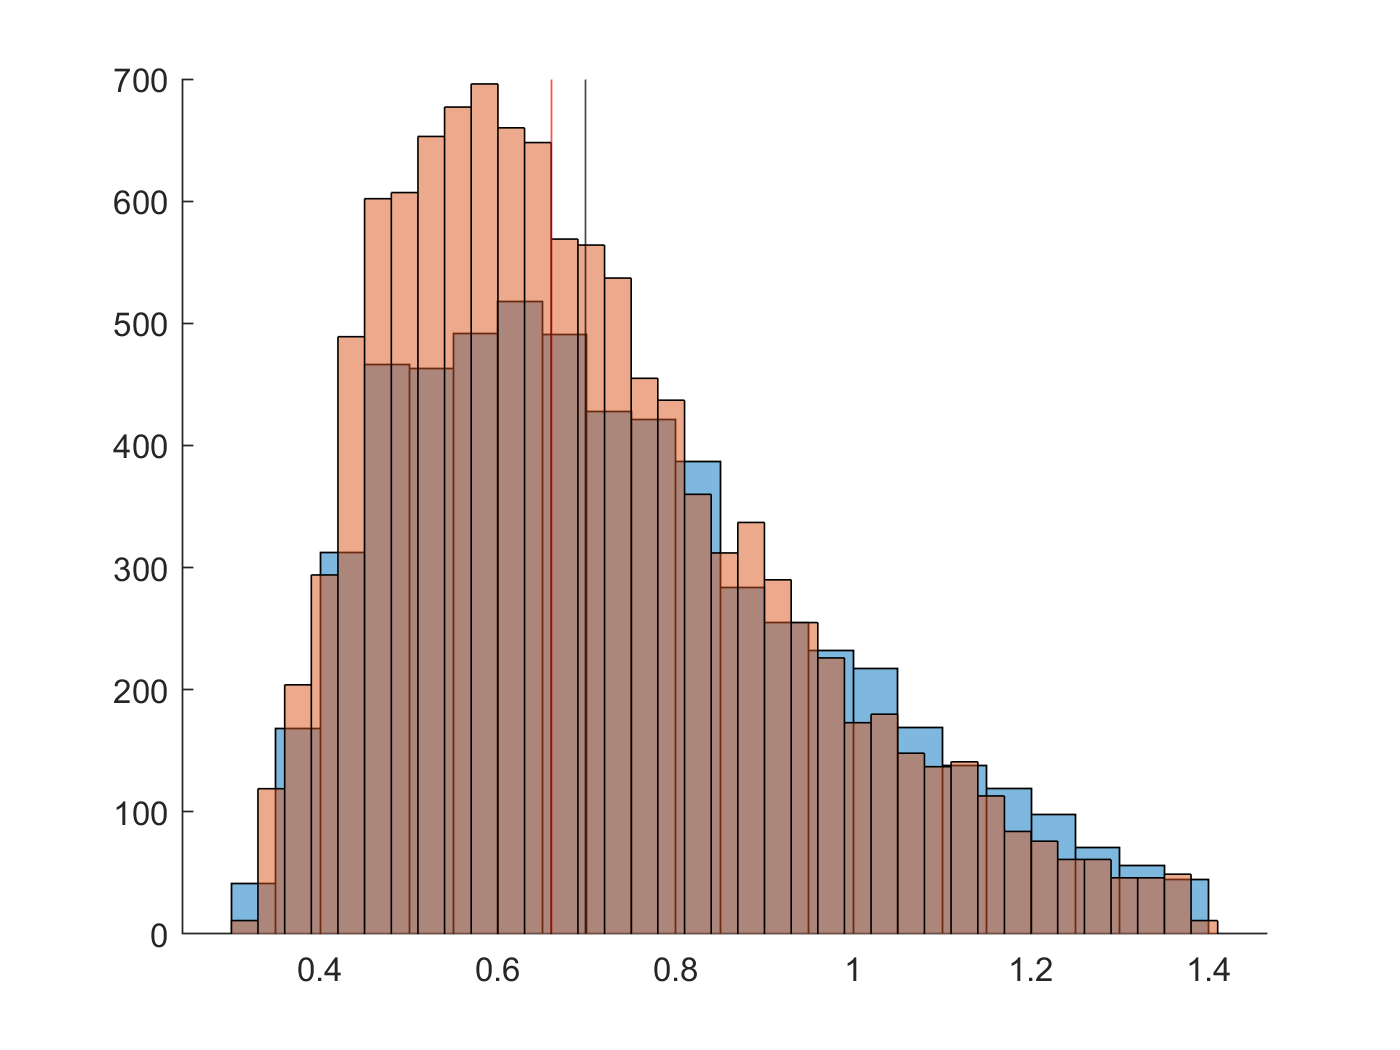


figure()
hold on
histogram(RT_Correct','FaceAlpha',0.5)
xline(nanmedian(RT_Correct),'Color','k')
histogram(RT_Incorrect','FaceAlpha',0.5)
xline(nanmedian(RT_Incorrect),'Color','r')